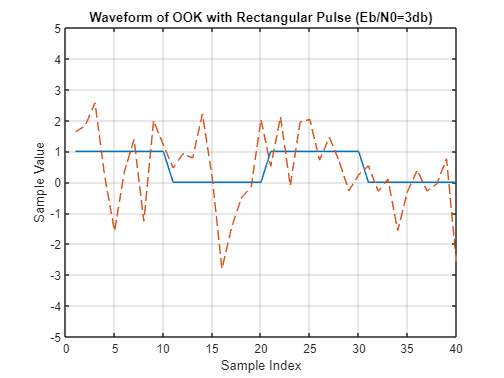

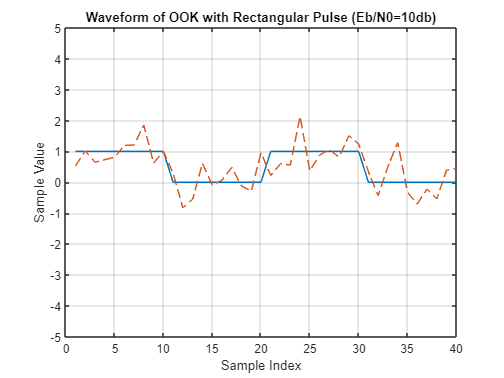

clear all;
close all; 
clc;
%%parameter
data_number = 10^5; % # of bits 
EbN0dB_vec = [3 10] ;% Eb/N0 in dB 
Fs=10; % sampling frequency (used to generate received samples
%% transmitter
Data_bit=(rand(1,data_number) > 0.5 ); % random bits
a=0;
b=0;
for k=1:data_number
    if Data_bit(k)==1
        a=a+1;
    else
        b=b+1;
    end 
end
%disp('bit1的機率'),a/data_number
%disp('bit0的機率'),b/data_number


p1=ones(1,Fs);% discrete‐time rectangular pulse that represents on
Data_pulse_array=(p1.')*Data_bit;
Data_pulse=reshape(Data_pulse_array,1,length(p1)*data_number);
for kk=1:length(EbN0dB_vec)
%% AWGN channel
[a b] = size(Data_pulse); 
EbN0dB = EbN0dB_vec(kk); 
EbN0 = 10^(EbN0dB/10); % EbN0 is now in linear scale
sgma = sqrt( 0.5/EbN0/2*10 );
noise = normrnd(0, sgma, a, b ) ;
Data_receive=Data_pulse+noise;% received samples 
%Data_receive=Data_pulse;
%% receiver
D_filtered=conv(Data_receive,p1);% MF output
index=1:length(Data_receive);
%plot(index(1:40),Data_pulse(1:40))
%ylim([-5 5])
%plot(index(1:40),Data_receive(1:40))



D_demapping=D_filtered(10:10:end)/10;% sampling at symbol rate 
% decsion based on D_demapping
D_demap_N = (D_demapping > 0.5); % >0.5: 1; <=0.5: 0
% BER computation
Error_num=sum(xor(D_demap_N,Data_bit));
BER(kk) = Error_num/data_number;
%fprintf('EbN0 in dB is %g\n',EbN0dB);
%fprintf('Bit error rate is %g\n',BER);
x=index(1:40);
tx=Data_pulse(1:40);
rx=Data_receive(1:40);
figure(kk)
plot(x,tx)
hold on
plot(x,rx,'--')
grid on

ylim([-5 5])
if kk==1
    title('Waveform of OOK with Rectangular Pulse (Eb/N0=3db)')
end
if kk==2
    title('Waveform of OOK with Rectangular Pulse (Eb/N0=10db)')
end
ylabel('Sample Value')
xlabel('Sample Index')
end

第一題 畫圖

x=index(1:40);
tx=Data_pulse(1:40);
rx=Data_receive(1:40);
figure(kk)
plot(x,tx)
hold on
plot(x,rx,'--')
grid on

ylim([-5 5])
if kk==1
    title('Waveform of OOK with Rectangular Pulse (Eb/N0=3db)')
end
if kk==2
    title('Waveform of OOK with Rectangular Pulse (Eb/N0=10db)')
end
ylabel('Sample Value')
xlabel('Sample Index')


2.f畫圖

%% generate plots
figure;
semilogy(EbN0dB_vec, BER,'o-');
hold
xlabel('Eb/N0 (dB), where Eb: average energy per bit');
ylabel('Bit Error Rate')
axis([0 12 1e-4 1e0])
title('OOK with Rectangular Pulse (Simulation)')


ebnodB = [0 2 4 6 8 10 11.5];
ebno = 10.^(ebnodB/10);
Pb = qfunc(sqrt(ebno));
semilogy(ebnodB,Pb,'*-')
legend('OOK (Simulation)','OOK(Theory)')
grid on